# clear memory, screen, and close all figures

clear, clc, close all;

## Process equation x[k] = sys(k, x[k-1], u[k]);

nx = 1;  % number of states
sys = @(k, xkm1, uk) xkm1/2 + 25*xkm1/(1+xkm1^2) + 8*cos(1.2*k) + uk; % (returns column vector)

## Observation equation y[k] = obs(k, x[k], v[k]);

ny = 1;                                           % number of observations
obs = @(k, xk, vk) xk^2/20 + vk;                  % (returns column vector)

## PDF of process noise and noise generator function

nu = 1;                                           % size of the vector of process noise
sigma_u = sqrt(10);
p_sys_noise   = @(u) normpdf(u, 0, sigma_u);
gen_sys_noise = @(u) normrnd(0, sigma_u);         % sample from p_sys_noise (returns column vector)

## PDF of observation noise and noise generator function

nv = 1;                                           % size of the vector of observation noise
sigma_v = sqrt(1);
p_obs_noise   = @(v) normpdf(v, 0, sigma_v);
gen_obs_noise = @(v) normrnd(0, sigma_v);         % sample from p_obs_noise (returns column vector)

## Initial PDF

p_x0 = @(x) normpdf(x, 0,sqrt(10)); % initial pdf

gen_x0 = @(x) normrnd(0, sqrt(10));               % sample from p_x0 (returns column vector)

## Transition prior PDF p(x[k] | x[k-1])

(under the suposition of additive process noise) p_xk_given_xkm1 = @(k, xk, xkm1) p_sys_noise(xk - sys(k, xkm1, 0));

## Observation likelihood PDF p(y[k] | x[k])

(under the suposition of additive process noise)

p_yk_given_xk = @(k, yk, xk) p_obs_noise(yk - obs(k, xk, 0));

## Number of time steps

T = 40;

## Separate memory space

x = zeros(nx,T);  y = zeros(ny,T);
u = zeros(nu,T);  v = zeros(nv,T);

## Simulate system

xh0 = 0;                                  % initial state
u(:,1) = 0;                               % initial process noise
v(:,1) = gen_obs_noise(sigma_v);          % initial observation noise
x(:,1) = xh0;
y(:,1) = obs(1, xh0, v(:,1));
for k = 2:T
   % here we are basically sampling from p_xk_given_xkm1 and from p_yk_given_xk
   u(:,k) = gen_sys_noise();              % simulate process noise
   v(:,k) = gen_obs_noise();              % simulate observation noise
   x(:,k) = sys(k, x(:,k-1), u(:,k));     % simulate state
   y(:,k) = obs(k, x(:,k),   v(:,k));     % simulate observation
end

## Separate memory

xh = zeros(nx, T); xh(:,1) = xh0;
yh = zeros(ny, T); yh(:,1) = obs(1, xh0, 0);

pf.k               = 1;                   % initial iteration number
pf.Ns              = 200;                 % number of particles
pf.w               = zeros(pf.Ns, T);     % weights
pf.particles       = zeros(nx, pf.Ns, T); % particles
pf.gen_x0          = gen_x0;              % function for sampling from initial pdf p_x0
pf.p_yk_given_xk   = p_yk_given_xk;       % function of the observation likelihood PDF p(y[k] | x[k])
pf.gen_sys_noise   = gen_sys_noise;       % function for generating system noise
%pf.p_x0 = p_x0;                          % initial prior PDF p(x[0])
%pf.p_xk_given_ xkm1 = p_xk_given_xkm1;   % transition prior PDF p(x[k] | x[k-1])

## Estimate state

for k = 2:T
   fprintf('Iteration = %d/%d\n',k,T);
   % state estimation
   pf.k = k;
   %[xh(:,k), pf] = particle_filter(sys, y(:,k), pf, 'multinomial_resampling');
   [xh(:,k), pf] = particle_filter(sys, y(:,k), pf, 'systematic_resampling');   
 
   % filtered observation
   yh(:,k) = obs(k, xh(:,k), 0);
end

Iteration = 2/40


Resampling ...


Iteration = 3/40


Resampling ...


Iteration = 4/40


Resampling ...


Iteration = 5/40
Iteration = 6/40


Resampling ...


Iteration = 7/40
Iteration = 8/40


Resampling ...


Iteration = 9/40
Iteration = 10/40


Resampling ...


Iteration = 11/40


Resampling ...


Iteration = 12/40


Resampling ...


Iteration = 13/40
Iteration = 14/40


Resampling ...


Iteration = 15/40
Iteration = 16/40


Resampling ...


Iteration = 17/40


Resampling ...


Iteration = 18/40


Resampling ...


Iteration = 19/40
Iteration = 20/40


Resampling ...


Iteration = 21/40


Resampling ...


Iteration = 22/40


Resampling ...


Iteration = 23/40


Resampling ...


Iteration = 24/40
Iteration = 25/40


Resampling ...


Iteration = 26/40


Resampling ...


Iteration = 27/40


Resampling ...


Iteration = 28/40
Iteration = 29/40


Resampling ...


Iteration = 30/40


Resampling ...


Iteration = 31/40
Iteration = 32/40


Resampling ...


Iteration = 33/40


Resampling ...


Iteration = 34/40


Resampling ...


Iteration = 35/40


Resampling ...


Iteration = 36/40


Resampling ...


Iteration = 37/40
Iteration = 38/40


Resampling ...


Iteration = 39/40


Resampling ...


Iteration = 40/40


Resampling ...


## Make plots of the evolution of the density

figure
hold on;

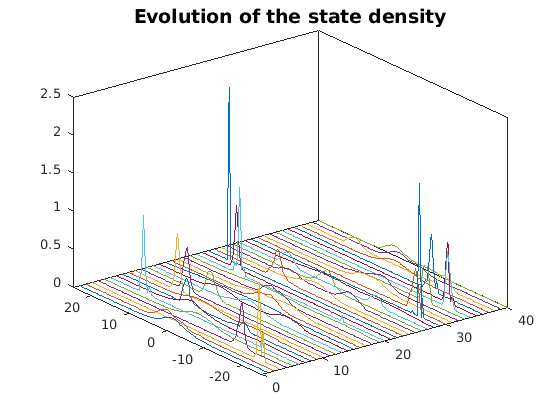

xi = 1:T;
yi = -25:0.25:25;
[xx,yy] = meshgrid(xi,yi);
den = zeros(size(xx));
xhmode = zeros(size(xh));

for i = xi
   % for each time step perform a kernel density estimation
   den(:,i) = ksdensity(pf.particles(1,:,i), yi,'kernel','epanechnikov');
   [~, idx] = max(den(:,i));

   % estimate the mode of the density
   xhmode(i) = yi(idx);
   plot3(repmat(xi(i),length(yi),1), yi', den(:,i));
end
view(3);
box on;
title('Evolution of the state density','FontSize',14)

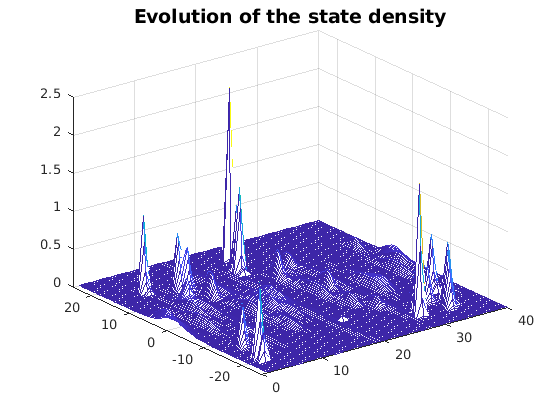


figure
mesh(xx,yy,den);   
title('Evolution of the state density','FontSize',14)

## plot of the state vs estimated state by the particle filter vs particle paths

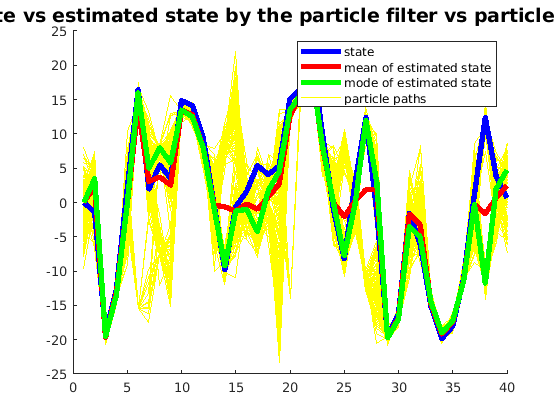

figure
hold on;
h1 = plot(1:T,squeeze(pf.particles),'y');
h2 = plot(1:T,x,'b','LineWidth',4);
h3 = plot(1:T,xh,'r','LineWidth',4);
h4 = plot(1:T,xhmode,'g','LineWidth',4);
legend([h2 h3 h4 h1(1)],'state','mean of estimated state','mode of estimated state','particle paths');
title('State vs estimated state by the particle filter vs particle paths','FontSize',14);

## plot of the observation vs filtered observation by the particle filter

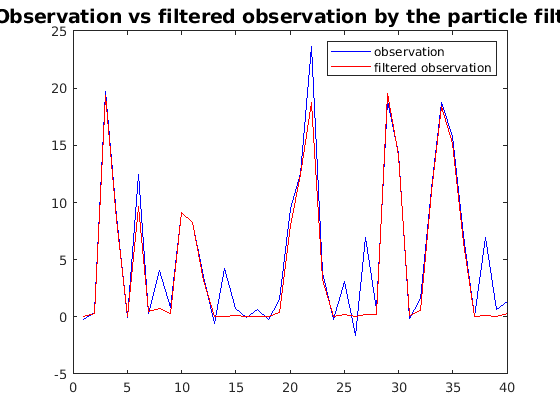

figure
plot(1:T,y,'b', 1:T,yh,'r');
legend('observation','filtered observation');
title('Observation vs filtered observation by the particle filter','FontSize',14);


return;